#                                              Homework 7

Collaborated with: Aditya Rathi

# Q1 (a)

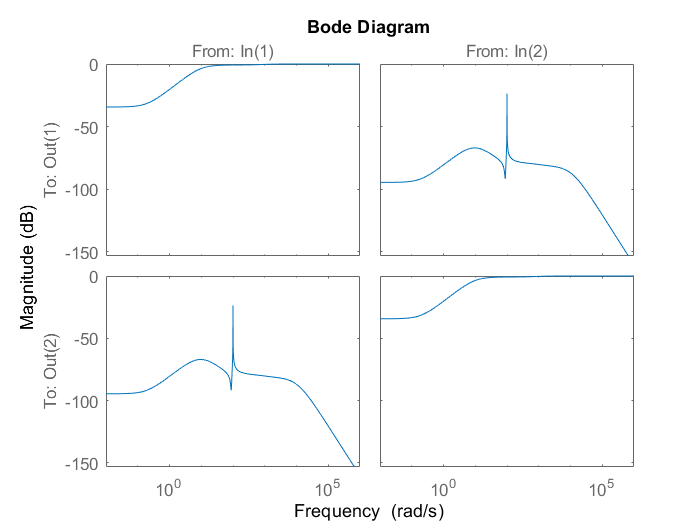

a = 100;
s = tf('s');    
G = minreal([s-a^2 a*(s+1);-a*(s+1) s-a^2]/(s^2 + (a*s)/50 + a^2));
Wt = eye(2)*(20*s+10)/(s+100);
Wp = eye(2)*(0.5*s+20)/(s+0.2);
[K,CL,GAM] = mixsyn(G,Wp,[],Wt);
S = eye(2) - feedback(G*K,eye(2));
bodemag(S)

isstable(S)

ans = logical
   1


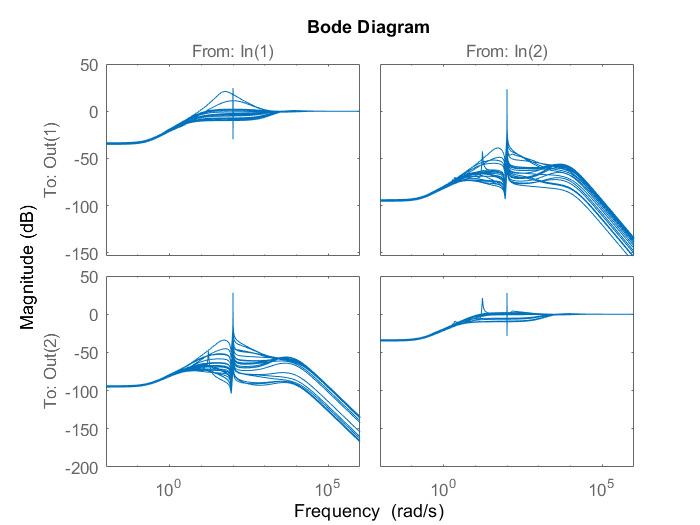

del_1 = ultidyn('del1',1);
del_2 = ultidyn('del2',1);
G_hat = (eye(2) + [del_1 0;0 del_2]*Wt)*G;
P = [Wp -Wp*G;eye(2) -G];
P_hat = [Wp -Wp*G_hat;eye(2) -G_hat];
S_vec = eye(2) - feedback(G_hat*K,eye(2));
bodemag(S_vec)

%N = lft(P_hat,K);
[STABMARG,WCU] = robuststab(S_vec);
mu_s = 1/STABMARG.LowerBound

mu_s = 1.8561

[PERFMARG,WCU] = robustperf(Wp*S_vec);
mu_p = 1/PERFMARG.LowerBound

mu_p = 2.7252

As mu is greater than 1 for both robust stability and robust performance, it is not RS and does not have RP

# Q1(b)

% Mu synthesis
[K,CLperf] = musyn(P_hat,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           122.6        55.98        56.47             2
    2           14.72        9.932        10.04             8
    3           5.438        5.235        5.269            34
    4           4.132        4.118        4.149            50
    5           3.599        3.613        3.729            54
    6           3.528        3.555        3.588            42
    7           3.526         3.49        3.497            46
    8           3.478        3.474        3.536            38
    9           3.503         3.47        3.481            36

Best achieved robust performance: 3.47



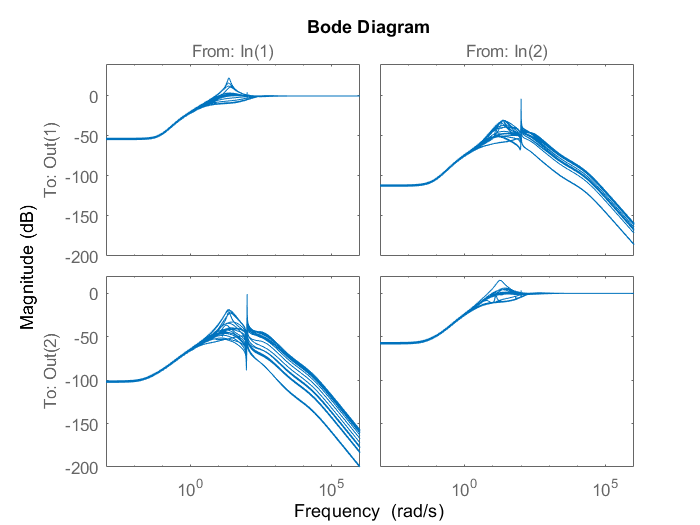

S = eye(2)-feedback(G_hat*K,eye(2)); 
bodemag(S)

N = lft(P_hat,K)

N =

  Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 70 states.
  The model uncertainty consists of the following blocks:
    del1: Uncertain 1x1 LTI, peak gain = 1, 2 occurrences
    del2: Uncertain 1x1 LTI, peak gain = 1, 2 occurrences

Type "N.NominalValue" to see the nominal value, "get(N)" to see all properties, and "N.Uncertainty" to interact with the uncertain elements.



stabmarg = robuststab(S); 
mu = 1/stabmarg.LowerBound

mu = 2.1907

perfmarg = robustperf(Wp*S);
mumult = 1/perfmarg.LowerBound

mumult = 3.3150

The RS/RP goals are not met for this system.

The robust stability and robust performance obtained from mixsyn(H-inf design) is better than the one obtained using musyn. From the bode plots, we can also observe that the sensitivity peaks have been either clipped off or reduced when muxsyn is used.